% Base paths and clearing
clear all
clc
addpath functions/SETUP/
addpath functions/SENSE/
addpath functions/THINK/
addpath functions/ACT/

% Setup Pi
[roverPi, blinkLED]= SETUP_pi("192.168.16.68");

% Setup Servos
roverServos = I2C_Servo_pHAT(roverPi);
% Setup Sensors
[adcDevice1, adcDevice2] = SETUP_adc(roverPi);

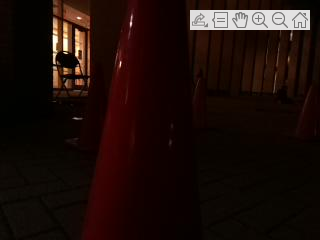

% Setup PiCam
roverCam = cameraboard(roverPi,'Resolution','320x240');
SETUP_piCam(roverCam);  

img = snapshotCustom(roverCam);

piCamWindow = figure('name','rover Pi Camera','NumberTitle','off','Visible','on');
figure(piCamWindow)
imshow(img,'Border','tight')

curvePlot = 1;
WPn = 1;

%while 1
    [steerAngle, velocity, WPn] = THINK_navigate(WPn, roverCam, adcDevice1, adcDevice2, piCamWindow, curvePlot) 

ans = 161

sharpData =     0.1395    2.1739    0.1607    0.2249         0


sharpDist =   429.8310   22.9335  362.6248  246.3265  655.3939


curveIR =     0.0499    0.0496    0.0485    0.0467    0.0443    0.0413    0.0380    0.0344    0.0306    0.0269    0.0232    0.0197    0.0165    0.0136    0.0110    0.0088    0.0069    0.0054    0.0041    0.0031    0.0023    0.0016    0.0012    0.0008    0.0006    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


steerAngle = -21.7500

velocity = 0.4996

steerAngle = -21.7500

velocity = 0.4996

WPn = 7

%     ACT_moveRover(roverServos, steerAngle, velocity)
%     pause(0.1)
%     ACT_moveRover(roverServos,0,0)
%end